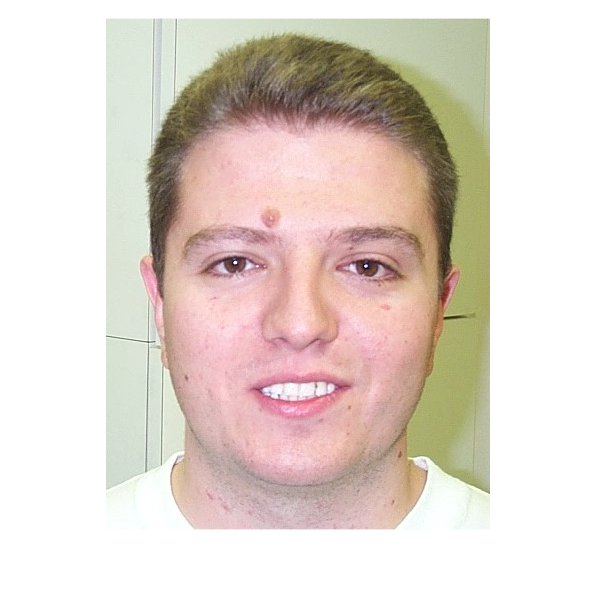

C1 = imread('db/DB0/db0_1.jpg');
imshow(C1)

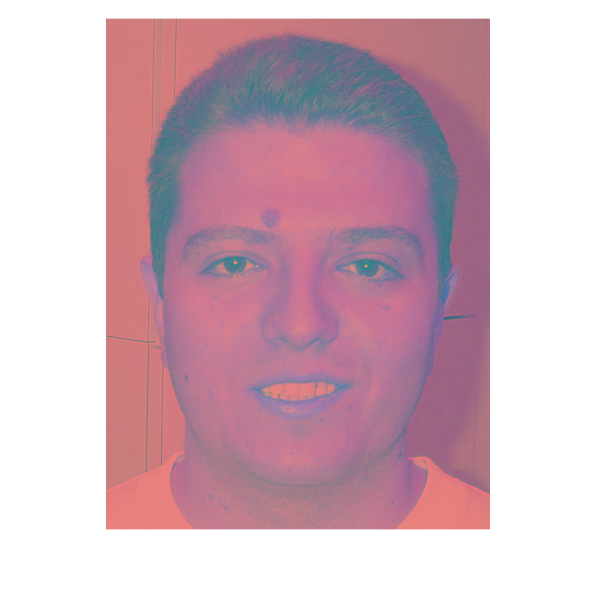

C2 = rgb2ycbcr(C1);
imshow(C2)

C3 = double(C2);
imshow(C3,[])

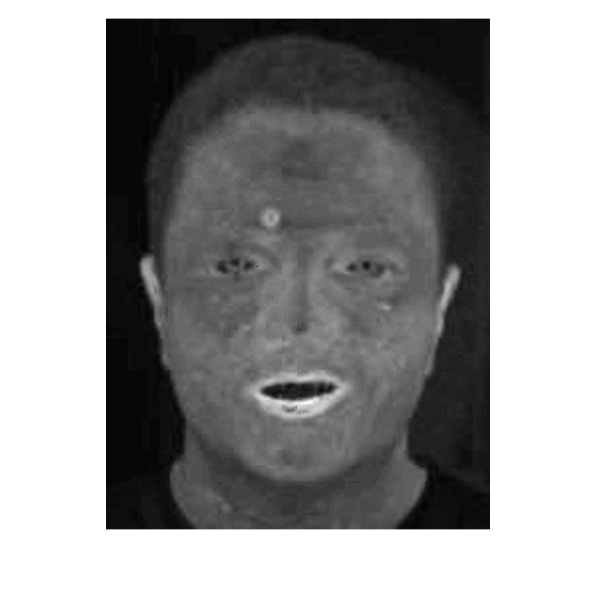





cb=C3(:,:,2);
cr=C3(:,:,3);

ccr=(cr).^2;
imshow(ccr,[])

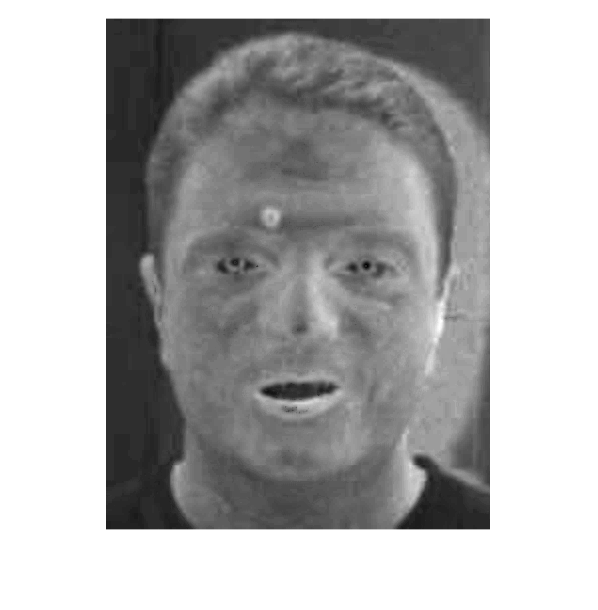


crcb=cr./cb;
imshow(crcb,[])

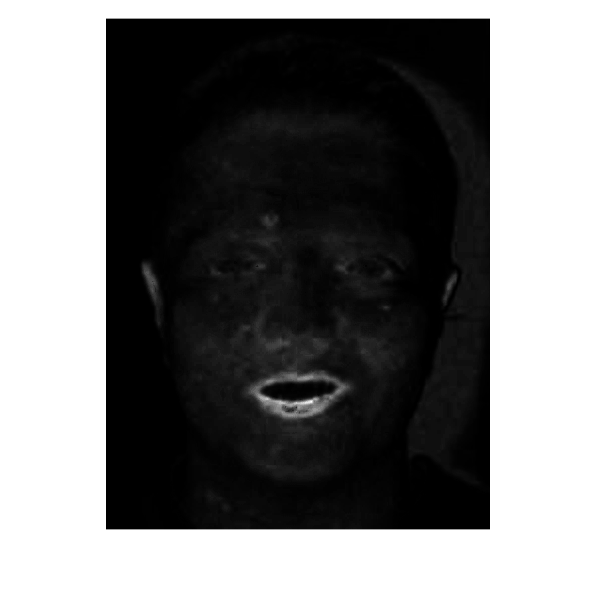






%Mouth Map
n = 0.95*mean(cr(:).^2)./(mean(cr(:)./cb(:)));

MouthMap = (ccr).*((ccr - n*(crcb)).^2);
imshow(MouthMap,[])



% Dilation 
se = strel(10);
result = imdilate(MouthMap,se);
imshow(MouthMap,[])

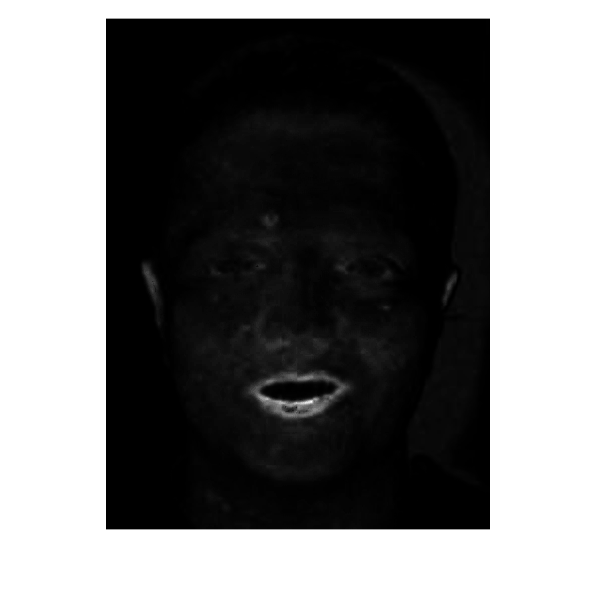


%diffrence och AND
result=(ccr-crcb).*(MouthMap);

%normaliz
result=(result./max(result(:)));
imshow(result,[])